clear all; clc;

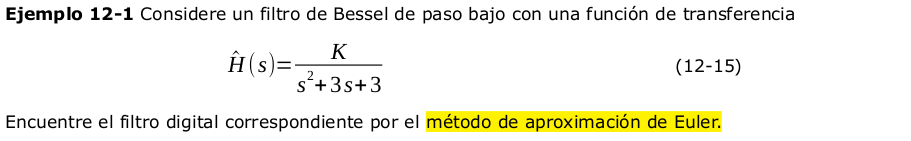


% función de transferencia - bessel
syms s, syms K 'real';
Hk(s)=K/(s^2+3*s+3)

$$Hk(s) = \frac{K}{s^{2}+3\,s+3}$$

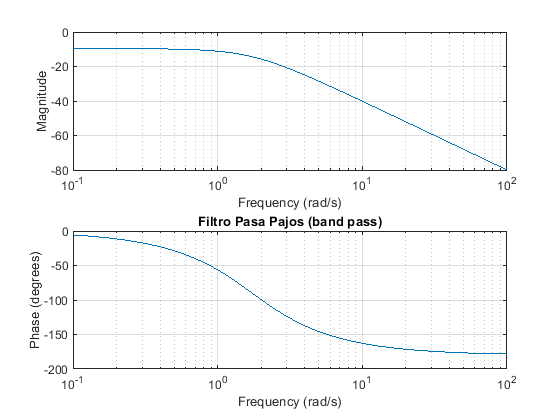

% dando un valor a K.
H(s)=subs(Hk(s),K=sym(1));

% respuesta en frecuencia s
% [B,A]=numden(H(s));
% b= sym2poly(collect(B));
% a= sym2poly(collect(A));
% w=logspace(-1,1);
% clf, freqs(b,a,w);
plotdb(collect(H(s)), -1,2); title('Filtro Pasa Pajos (band pass)');


% Transformación por Integración numérica - método de euler
syms z, syms T 'real';
HzT(z)=subs( H(s), s=(1-z^-1)/T) ;
HzT(z)=collect(HzT(z),z^-1 )

$$HzT(z) = \frac{T^{2}}{3\,T-\frac{3\,T+2}{z}+3\,T^{2}+\frac{1}{z^{2}}+1}$$

% periodo de muestreo;
Hz(z)=subs(HzT(z),T=sym(1))

$$Hz(z) = \frac{1}{\frac{1}{z^{2}}-\frac{5}{z}+7}$$

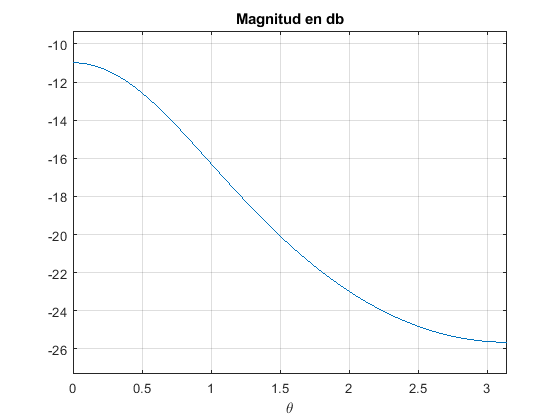

% respuesta en frecuencia
syms theta 'real';
clf; ezplot(10*log(abs(Hz(exp(j*theta)))),[0,pi]),
title('Magnitud en db'); grid on;

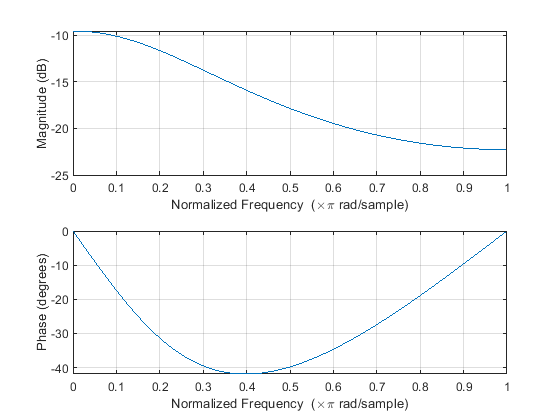


% respuesta en frecuencia
[Bz,Az]=numden(Hz(z));
bz=sym2poly(Bz); az=sym2poly(Az);
clf; freqz(bz, az)

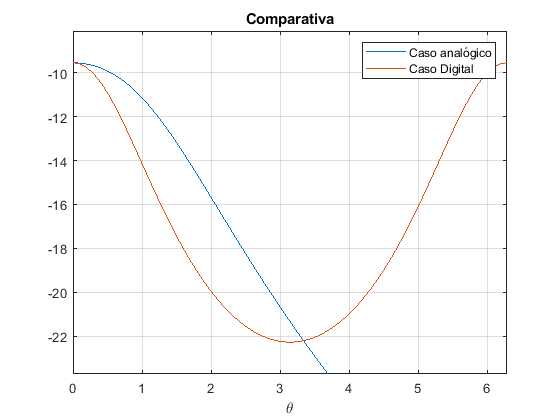


%numerator = [1,0,0];
%denominator = [1,2,3];
%ts = 0.1;
%sys = tf(bz,az,ts,'Variable','z^-1')
%freqz(bz, az,2048)


% comparativa caso analógico - caso digital


syms wN 'real';
HwN(wN)=subs(H(s), s=j*wN/T );
HwN(wN)=subs(HwN(wN), T,1 );
clf; ezplot(20*log10(abs( HwN(wN) )),[0,2*pi]); hold on ;

Hz(s)=subs(Hz(s), T,1 );
ezplot(20*log10(abs( Hz(exp(j*theta) ))),[0,2*pi]);

legend('Caso analógico', 'Caso Digital' );
title('Comparativa'); hold off; grid on;